ranges = {};
angles = {};
for x = 1:length(samplePackets)
    currentPacket = samplePackets{x};
    
    LSN = currentPacket(1, 4);
    FSA = double(bitor(bitshift(uint16(currentPacket(1, 6)), 8), uint16(currentPacket(1, 5)), 'uint16'));
    LSA = double(bitor(bitshift(uint16(currentPacket(1, 8)), 8), uint16(currentPacket(1, 7)), 'uint16'));
   
    AngleFSA = double(bitshift(FSA, -1) / 64);
    AngleLSA = double(bitshift(LSA, -1) / 64);
    diffAngle = mod((AngleLSA - AngleFSA),360);
    
    rawSi = uint8(currentPacket(:, 11:end));
    Si = zeros(1, LSN);
    for i = 1:2:length(rawSi)
        Si((i + 1) / 2) = double(bitor(bitshift(uint16(rawSi(1, i + 1)), 8), uint16(rawSi(1, i)), 'uint16'));
    end
    
    AngleSi = zeros(1, LSN);
    if Si(1) == 0
        AngleSi(1) = AngleFSA;
    else
        AngleSi(1) = AngleFSA + atan(21.8*((155.3-Si(1))/(155.3*Si(1))));
    end

    for i = 2:LSN - 1
        if Si(i) == 0
            AngleSi(i) = ((diffAngle / (LSN - 1)) * (i - 1) + AngleFSA);
        else
            AngleSi(i) = ((diffAngle / (LSN - 1)) * (i - 1) + AngleFSA) + atan(21.8*((155.3-Si(i))/(155.3*Si(i))));
        end
    end

    if Si(LSN) == 0
        AngleSi(LSN) = AngleLSA;
    else
        AngleSi(LSN) = AngleLSA + atan(21.8*((155.3-Si(end))/(155.3*Si(end))));
    end
    
    Si = Si / 4000;

    ranges{end+1} = Si;
    angles{end+1} = AngleSi;

end

testAngles = zeros(1,400);
testRanges = zeros(1,400);
idx = 0;
for i = 1:10
    currentAngles = angles{i};
    currentRanges = ranges{i};
    for j = 1:40
        idx = idx + 1;
        testAngles(idx) = currentAngles(j);
        testRanges(idx) = currentRanges(j);
    end
end

Angles = {};
Ranges = {};
count = 0;
testAngles = zeros(1,400);
testRanges = zeros(1,400);

for k = 1:floor(numel(angles)/10)
    idx = 0;
    for i = 1+count:10+count
        currentAngles = angles{i};
        currentRanges = ranges{i};
        for j = 1:40
            idx = idx + 1;
            testAngles(idx) = currentAngles(j);
            testRanges(idx) = currentRanges(j);
        end
    end
    count = count + 10;
    Angles{end+1} = testAngles;
    Ranges{end+1} = testRanges;
end

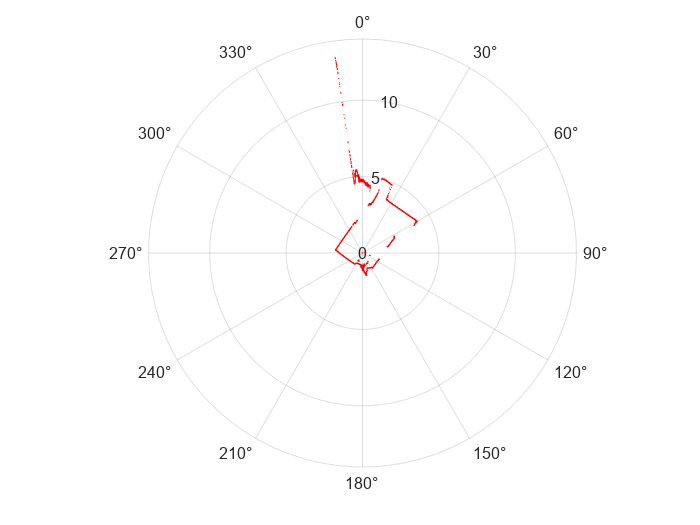

for i = 1:numel(Angles)
    polarplot(deg2rad(Angles{i}), Ranges{i}, 'r.', 'MarkerSize', 1);

    pax = gca;
    pax.ThetaZeroLocation = 'top';
    pax.ThetaDir = 'clockwise';
end